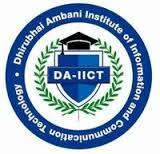

# CT303: Digital Communication

# Lab 4

## **Akshar Panchani**

## **202101522**

24-10-23

# Question1: 

(a) Problem 4.17 and 4.24

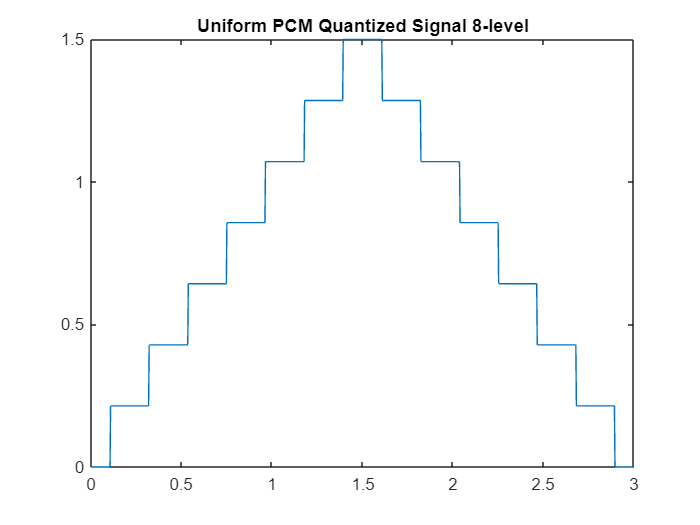

t = linspace(0, 3, 1000);

% Define the signal x(t)
x = zeros(size(t));
x(t >= 0 & t < 1.5) = t(t >= 0 & t < 1.5);
x(t >= 1.5 & t <= 3) = -t(t >= 1.5 & t <= 3) + 3;

% Define quantization levels for an 8-level PCM
quantization_levels_8 = linspace(min(x), max(x), 8);

% Quantize the signal
quantized_signal_8 = interp1(quantization_levels_8, quantization_levels_8, x, 'nearest');


figure;
plot(t, quantized_signal_8);
title('Uniform PCM Quantized Signal 8-level');

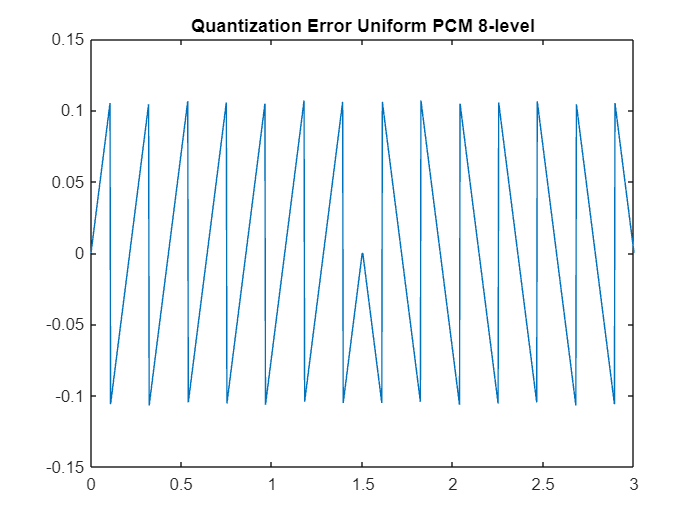

% Calculate the quantization error
quantization_error_8 = x - quantized_signal_8;

% Plot the quantization error
figure;
plot(t, quantization_error_8);
title('Quantization Error Uniform PCM 8-level');

% Calculate the SQNR for 8-level Uniform PCM
signal_power = mean(x.^2);
noise_power = mean(quantization_error_8.^2);
sqnr_8 = 10 * log10(signal_power / noise_power);
disp(['SQNR for 8-level Uniform PCM: ' num2str(sqnr_8) ' dB']);

SQNR for 8-level Uniform PCM: 22.9356 dB


A-> 4.17(16 levels)

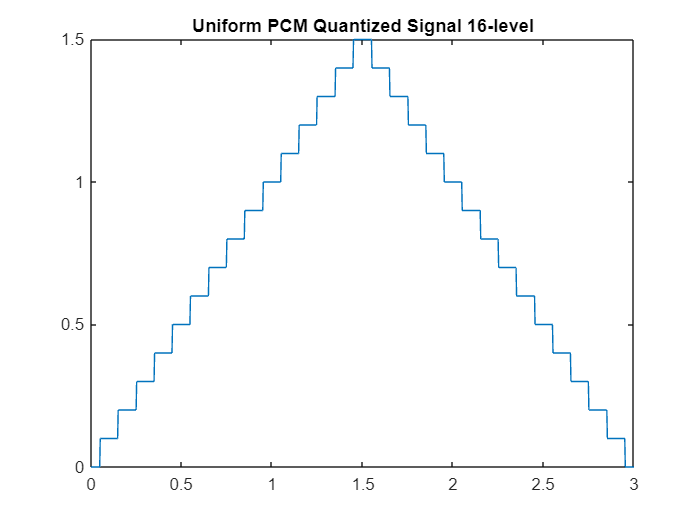

t = linspace(0, 3, 1000);

% Define the signal x(t)
x = zeros(size(t));
x(t >= 0 & t < 1.5) = t(t >= 0 & t < 1.5);
x(t >= 1.5 & t <= 3) = -t(t >= 1.5 & t <= 3) + 3;

% Define quantization levels for an 8-level PCM
quantization_levels_16 = linspace(min(x), max(x), 16);

% Quantize the signal
quantized_signal_16 = interp1(quantization_levels_16, quantization_levels_16, x, 'nearest');

figure;
plot(t, quantized_signal_16);
title('Uniform PCM Quantized Signal 16-level');

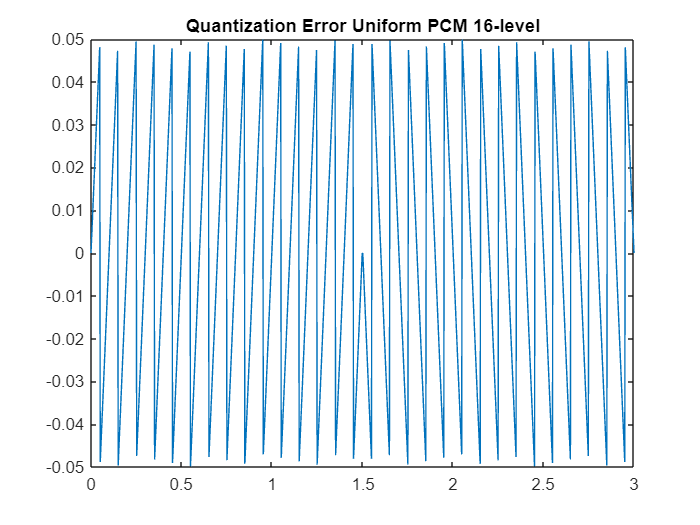

% Calculate the quantization error
quantization_error_16 = x - quantized_signal_16;

figure;
plot(t, quantization_error_16);
title('Quantization Error Uniform PCM 16-level');

% Calculate the SQNR for 16-level Uniform PCM
signal_power = mean(x.^2);
noise_power = mean(quantization_error_16.^2);
sqnr_16 = 10 * log10(signal_power / noise_power);
disp(['SQNR for 16-level Uniform PCM: ' num2str(sqnr_16) ' dB']);

SQNR for 16-level Uniform PCM: 29.5555 dB


A-> 4.24

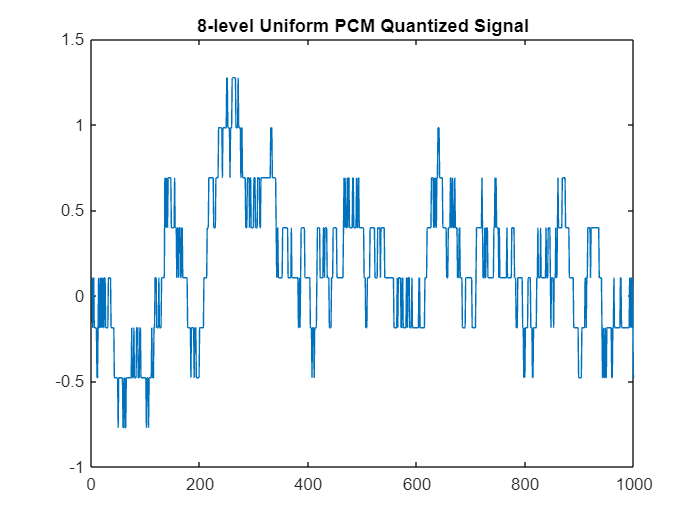

num_samples = 1000;
sigma_w = 0.1; % Standard deviation of the white Gaussian noise

% Simulate the Gauss-Markov process
X = zeros(1, num_samples);
w = sigma_w * randn(1, num_samples); % Generate white Gaussian noise

for n = 2:num_samples
    X(n) = 0.98 * X(n - 1) + w(n);
end

% Part a: Design an 8-level Uniform PCM quantizer for the Gauss-Markov Process
quantization_levels_8 = linspace(min(X), max(X), 8);
quantized_signal_8 = interp1(quantization_levels_8, quantization_levels_8, X, 'nearest');

% Plot the quantized output for 8-level Uniform PCM
figure;
plot(quantized_signal_8);
title('8-level Uniform PCM Quantized Signal');

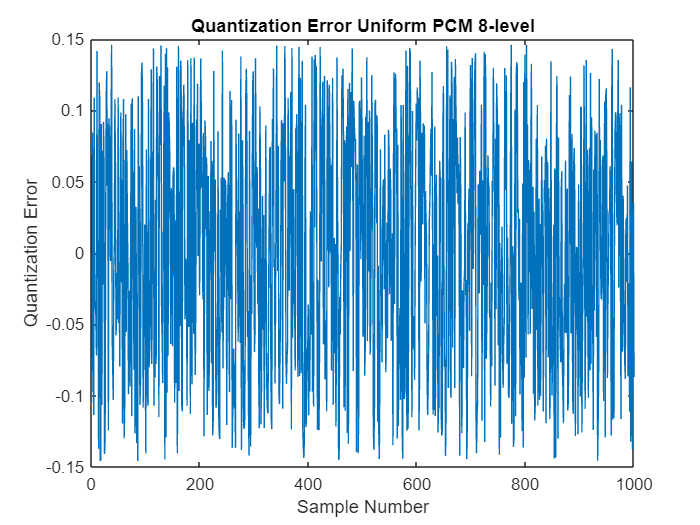


% Part b: Plot the Quantization Error for the Gauss-Markov Process
quantization_error_8 = X - quantized_signal_8;

% Plot the quantization error for 8-level Uniform PCM
figure;
plot(quantization_error_8);
title('Quantization Error Uniform PCM 8-level');
xlabel('Sample Number');
ylabel('Quantization Error');


% Part c: Calculate SQNR for 8-level Uniform PCM
signal_power = mean(X.^2);
noise_power = mean(quantization_error_8.^2);
sqnr_8 = 10 * log10(signal_power / noise_power);
disp(['SQNR for 8-level Uniform PCM: ' num2str(sqnr_8) ' dB']);

SQNR for 8-level Uniform PCM: 13.6356 dB


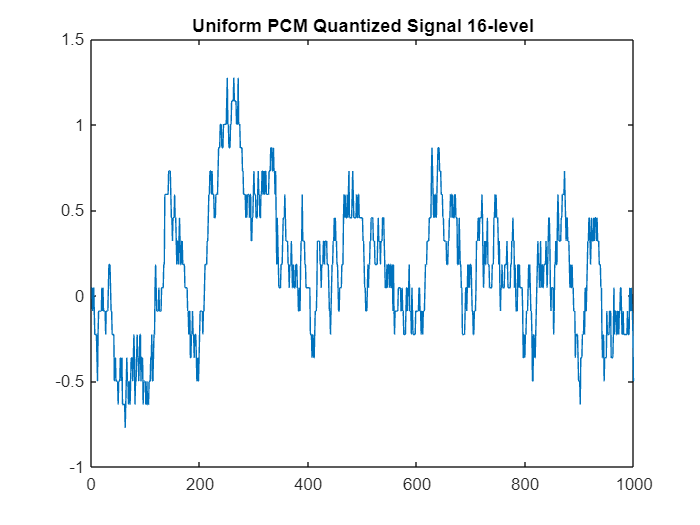


% Part d: Repeat for a 16-level Uniform PCM for the Gauss-Markov Process
quantization_levels_16 = linspace(min(X), max(X), 16);
quantized_signal_16 = interp1(quantization_levels_16, quantization_levels_16, X, 'nearest');

figure;
plot(quantized_signal_16);
title('Uniform PCM Quantized Signal 16-level');

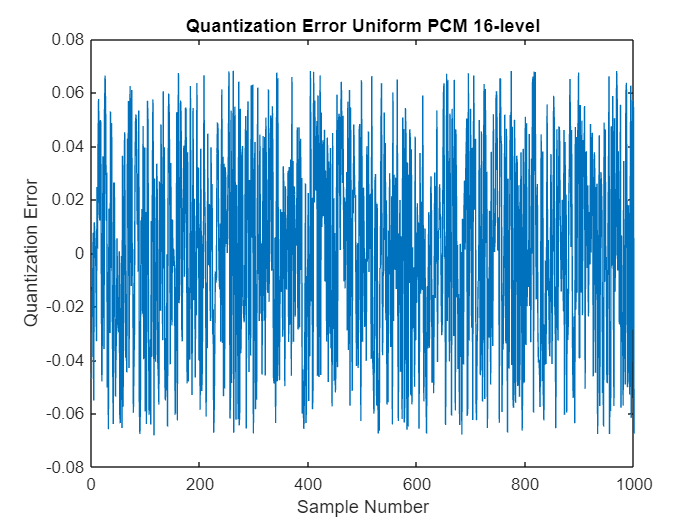


% Calculate the quantization error for 16-level Uniform PCM
quantization_error_16 = X - quantized_signal_16;

% Plot the quantization error for 16-level Uniform PCM
figure;
plot(quantization_error_16);
title('Quantization Error Uniform PCM 16-level');
xlabel('Sample Number');
ylabel('Quantization Error');


% Calculate SQNR for 16-level Uniform PCM
signal_power = mean(X.^2);
noise_power = mean(quantization_error_16.^2);
sqnr_16 = 10 * log10(signal_power / noise_power);
disp(['SQNR for 16-level Uniform PCM: ' num2str(sqnr_16) ' dB']);

SQNR for 16-level Uniform PCM: 20.6381 dB


B-> 4.18

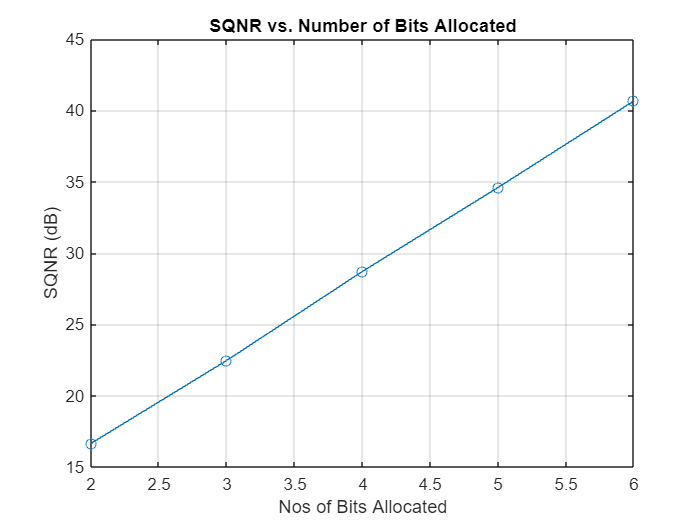

% Parameters
num_samples = 1000;
mu = 0; % Mean
sigma = 1; % Standard deviation

% Generate a Gaussian sequence with mean 0 and variance 1
gaussian_sequence = sigma * randn(1, num_samples) + mu;

% Initialize variables to store SQNR for different numbers of bits
bit_levels = [2, 3, 4, 5, 6]; % Number of bits allocated

% Initialize the array to store SQNR values
sqnr_values = zeros(size(bit_levels));

for i = 1:length(bit_levels)
    % Calculate the number of quantization levels based on bits
    num_levels = 2^bit_levels(i);
    
    % Calculate the step size for quantization
    step_size = (2 * sigma) / num_levels;
    
    % Quantize the Gaussian sequence
    quantized_sequence = round(gaussian_sequence / step_size) * step_size;
    
    % Calculate the quantization error
    quantization_error = gaussian_sequence - quantized_sequence;
    
    % Calculate SQNR (Signal-to-Quantization-Noise Ratio) in dB
    signal_power = var(gaussian_sequence);
    noise_power = var(quantization_error);
    sqnr_values(i) = 10 * log10(signal_power / noise_power);
end

figure;
plot(bit_levels, sqnr_values, '-o');
title('SQNR vs. Number of Bits Allocated');
xlabel('Nos of Bits Allocated');
ylabel('SQNR (dB)');
grid on;

B-> 4.21

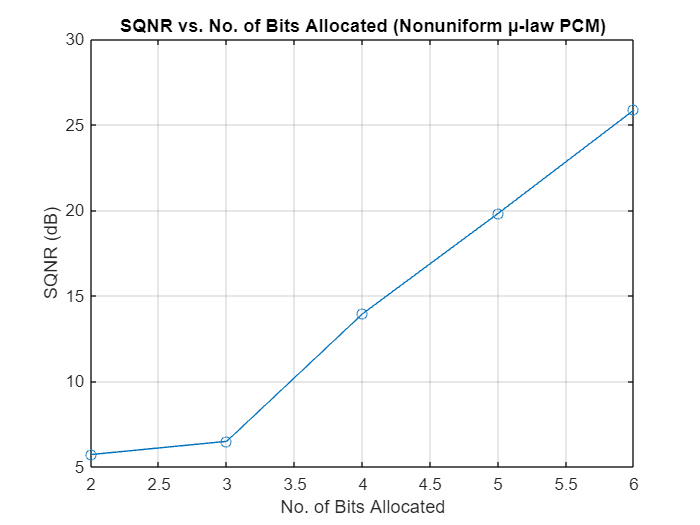

num_samples = 1000;
mu = 255; % µ-law parameter
sigma = 1; % Standard deviation

% Generate a Gaussian sequence with mean 0 and variance 1
gaussian_sequence = sigma * randn(1, num_samples);

% Define the µ-law companding function
u_law_companding = @(x, mu) sign(x) .* log(1 + mu * abs(x)) / log(1 + mu);

% Define the inverse µ-law companding function
u_law_inverse_companding = @(y, mu) sign(y) .* (1 / mu) .* ((1 + mu).^abs(y) - 1);

% Initialize variables to store SQNR for different numbers of bits
bit_levels = [2, 3, 4, 5, 6]; % Number of bits allocated

% Initialize the array to store SQNR values
sqnr_values = zeros(size(bit_levels));

for i = 1:length(bit_levels)
    % Calculate the number of quantization levels based on bits
    num_levels = 2^bit_levels(i);
    
    % Apply µ-law companding and inverse companding
    companded_sequence = u_law_companding(gaussian_sequence, mu);
    quantized_sequence = round(companded_sequence * (num_levels / 2));
    decompanded_sequence = quantized_sequence / (num_levels / 2);
    decompanded_sequence = u_law_inverse_companding(decompanded_sequence, mu);
    
    % Calculate the quantization error
    quantization_error = gaussian_sequence - decompanded_sequence;
    
    % Calculate SQNR (Signal-to-Quantization-Noise Ratio) in dB
    signal_power = var(gaussian_sequence);
    noise_power = var(quantization_error);
    sqnr_values(i) = 10 * log10(signal_power / noise_power);
end

% Plot SQNR as a function of the number of bits allocated
figure;
plot(bit_levels, sqnr_values, '-o');
title('SQNR vs. No. of Bits Allocated (Nonuniform µ-law PCM)');
xlabel('No. of Bits Allocated');
ylabel('SQNR (dB)');
grid on

# Question2:

Plot the quantization error and determine the corresponding SQNR. For the predictor, you can use the normalized LMS algorithm defined by the three consecutive equations in problem 3.40.

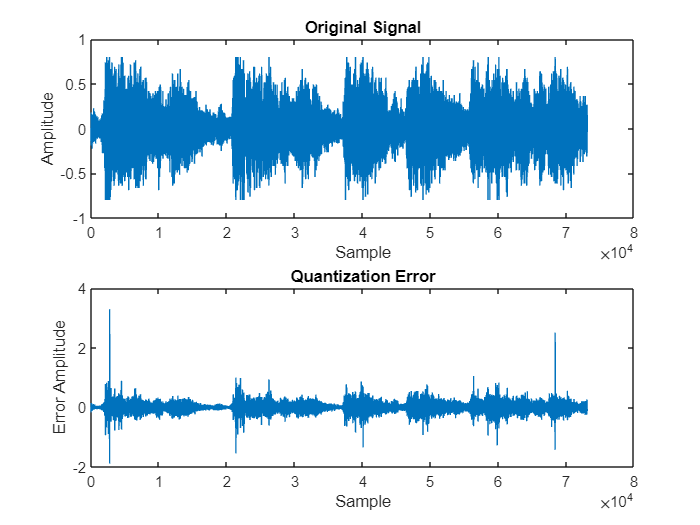

load handel.mat;

bit_depth = 8; % Number of bits per sample
audio_signal = y;

quantized_signal = zeros(size(audio_signal));
prediction_error = zeros(size(audio_signal));

% DPCM predictor parameters
N = length(audio_signal);
alpha = 0.02; % LMS step size
W = zeros(1, 2); % Predictor coefficients [W1, W2]
U = [0, 0]; % Delay line (previous values)

% Perform DPCM quantization
for n = 1:N
    % Make prediction
    prediction = W * U.';
    
    % Calculate prediction error
    prediction_error(n) = audio_signal(n) - prediction;
    
    % Quantize the prediction error
    quantized_error = round(prediction_error(n) * (2^(bit_depth - 1)));
    
    % Update predictor coefficients using LMS
    W = W + alpha * quantized_error * U;
    
    % Update delay line
    U = [audio_signal(n), U(1)];
    
    % Reconstruct the quantized signal
    quantized_signal(n) = prediction + quantized_error / (2^(bit_depth - 1));
end

signal_power = sum(audio_signal.^2) / N;
quantization_error_power = sum((audio_signal - quantized_signal).^2) / N;
SQNR = 10 * log10(signal_power / quantization_error_power);

figure;
subplot(2, 1, 1);
plot(audio_signal);
title('Original Signal');
xlabel('Sample');
ylabel('Amplitude');
subplot(2, 1, 2);
plot(prediction_error);
title('Quantization Error');
xlabel('Sample');
ylabel('Error Amplitude');

audiowrite('quantized_audio.wav', quantized_signal, Fs);

disp(['SQNR (dB): ', num2str(SQNR)]);

SQNR (dB): 38.7891
